# Algoritmos Numéricos por Computadora

# Examen Final - Otoño 2019

**Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).**

**Sube tu archivo resultado a comunidad **$\to$** Examen Final antes de las 2pm.**

**Al correr tu script deben desplegarse los resultados.**

**1a.** Escribe, al final del script, la función * jacobiana(f,x)* que calcula numéricamente la matriz jacobiana de la función vectorial $f$ en el vector $x$.

**1b. **Escribe, al final del script, el método de *Newton-Raphson *de varias variables modificado para que no reciba la matriz jacobiana sino que la calcule en cada iteración utilizando la función del problema 1. *NewtonRaphsonVV(f,x)*

**2. **Utiliza el (nuevo) método de Newton-Raphson de varias variables para determinar puntos de intersección entre la circunferencia $x^2 +y^2 =3$ y la hipérbola $\textrm{xy}=1$.

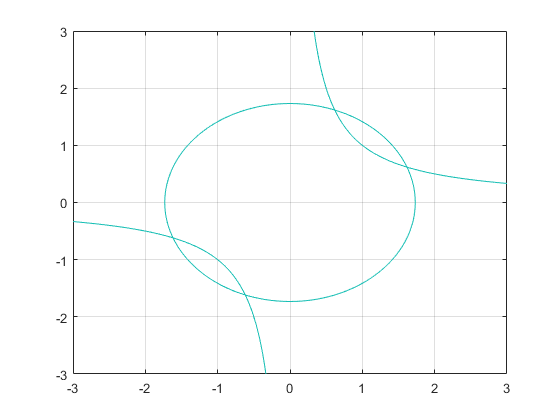

% Solución
f1 = @(x,y) x.^2 + y.^2 - 3;
zhandle1 = fcontour(f1,[-3 3 -3 3]);
zhandle1.LevelList = 0;
f2 = @(x,y) x.*y - 1 ;
hold on;
zhandle2 = fcontour(f2, [-3 3 -3 3]);
zhandle2.LevelList = 0;
grid on;
hold off;

f = @(x) [
    x(1)^2 + x(2)^2 - 3;
    x(1)*x(2) - 1 ];
x0 = [0.5; 1.5];
[x,~] = NewtonRaphsonVVn(f,x0)

x =     0.6180
    1.6180


% y los puntos simétricos: 
% % [1.6180;0.6180], [-0.6180;-1.6180] y [-1.6180;-0.6180]

**3.** Usando uno de los métodos vistos en clase para encontrar raíces de ecuaciones, calcula  una aproximación a $\sqrt[3]{25}\ldotp$

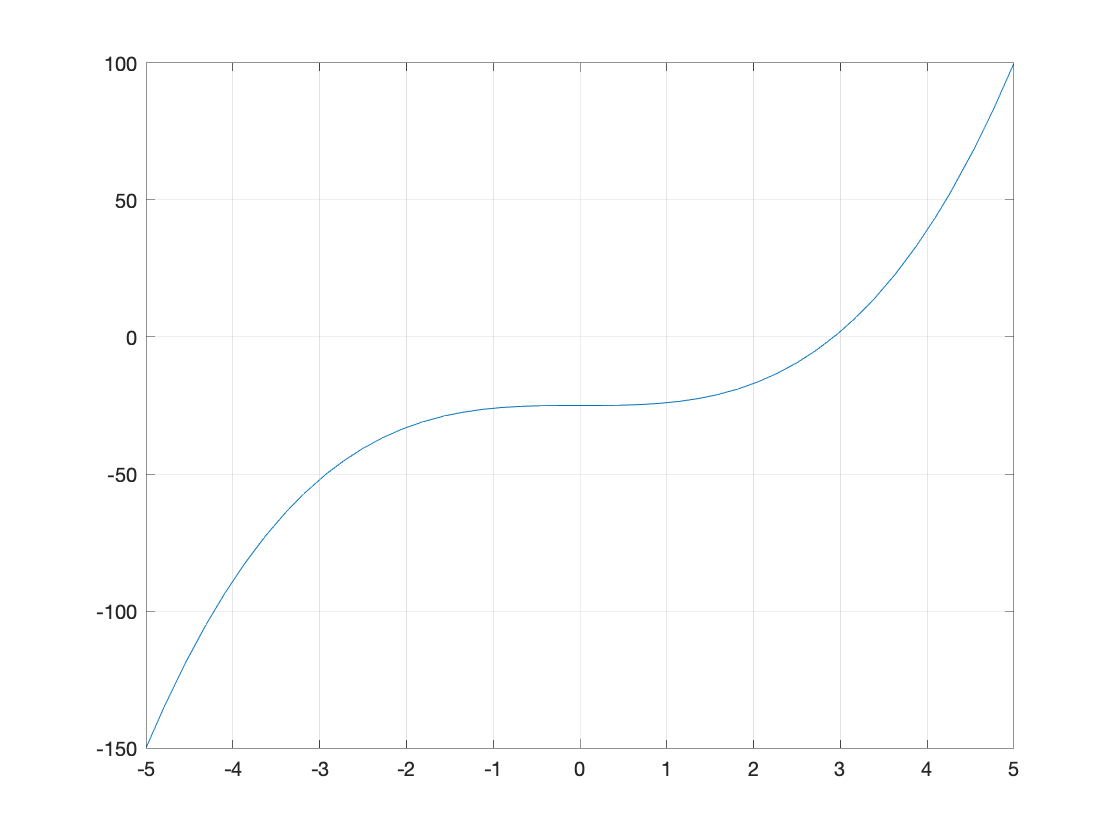

% Solución
f = @(x) x.^3 - 25;
fplot(f);
grid on;

% (2.5,3)
[x,~] = newtonRaphson(f,0.01)

x = 2.9240

x^3

ans = 25

**4.** Para simular el crecimiento de una población se utiliza el modelo logístico:


$$\frac{\mathrm{d}}{\mathrm{d}t}p=k_{\textrm{gm}} \left(1-\frac{p}{p_{\max } }\right)p$$


donde $p$ es la población, $k_{\textrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y $p_{\max }$ es la capacidad de carga. Simula la población mundial entre 1950 y 2020. Para la simulación utiliza las siguientes condiciones iniciales y valores de parametros: 

$p_0$ (en 1950) = 2,555 millones de personas, $k_{\textrm{gm}} =0\ldotp 026$/año y $p_{\max }$= 12,000 millones de personas.

En la simulación, usa los métodos de Euler y RK4 (con la misma h) para encontrar ¿cuántos millones de personas habrá en 2020? 

¿Por qué los resultados son diferentes al usar los dos métodos? ¿Cuál crees que es más exacto? ¿Por qué?

% Solución
kgm = 0.026;            % per year
pMax = 12;
pdot = @(t, p) kgm*(1-p/pMax)*p;
t0=1950

t0 = 1950

p0 = 2.555;  
tf = 2020;
[t,p] = ivpsV(pdot, p0, 0, tf-t0, 5, 'rk4');
p2020 = p(end)

p2020 = 0

plot(t+t0,p);
hold on;
[t,p] = ivpsV(pdot, p0, 0, tf-t0, 5, 'Euler');
p2020 = p(end)

p2020 = 0

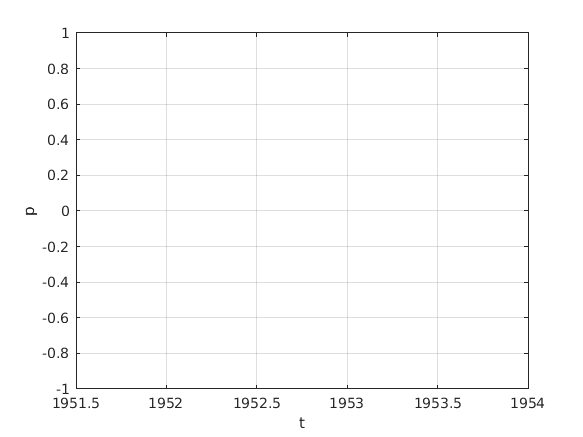

plot(t+t0,p);
hold off;
grid on;
xlabel('t');
ylabel('p');
grid on;

**5.** Si se drena el agua desde un tanque cilíndrico vertical abriendo una válvula en la base, el liquido fluirá rápido cuando el tanque esté lleno y despacio cuando se drene. Como resultado, la tasa a la que el nivel del agua disminuye es:

$\frac{\mathrm{d}}{\mathrm{d}t}y=-k\sqrt{y}$               ($y$ es el nivel del agua en metros y $t$ es el tiempo en minutos)

donde $k$ es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero. 

¿En cuántos minutos se vacía un tanque si el nivel inicial del agua en el tanque es de 3m y $k=0\ldotp 06$?

% Solución numérica
k = 0.06;
ydot = @(t, y) -k*sqrt(y);
y0 = 3;
% Hacemos pruebas con tf y h para descubrir el tiempo en que y = 0;
tf = 57;
[t,p] = ivpsV(ydot, y0, 0, tf, 0.5, 'rk4');
plot(t,p);

Error using plot
Vectors must be the same length.

grid on;
xlabel('t');
ylabel('y');
grid on;
hold on;
% Solucion analitica
syms y(t) 
eqn = diff(y,t) == -k*sqrt(y);
yG = dsolve(eqn);
cond = y(0) == y0;
yP = dsolve(eqn,cond)
fplot(yP(2), [0 tf]);
hold off;
tvs = solve(yP(2));
tv = double(tvs(1))

**6. ** Explica por qué el siguiente programa imprime 'Suma incorrecta'

num2hex(0.1)

ans = '3fb999999999999a'

suma = 0;
for i=1:10
    suma = suma + 0.1;
end
if (suma == 1)
    disp('Suma correcta')
else
    disp('Suma incorrecta')
end

Suma incorrecta



$$0\ldotp 1=3\textrm{fb999999999999a}$$


notaremos que el bit de signo es 0 (número positivo), el exponente es:


$$e=\left(\textrm{be}=512+256+128+64+32+16+8+2+1=1019\right)-1023=-4$$


Mientras tanto el binario para los 52 bits restantes viene dado por:

1001100110011001100110011001100110011001100110011010,

que al pasarlo a decimal, da como resultado

2702159776422298

Ahora 


$$x=\left(1+\frac{270215977642298}{2^{52} }\right)*2^{-4} \approx 0\ldotp 99999999999$$


Esto es, hay un error de cálculo a la hora de efectuar la suma, causando que el resultado de la misma no sea la representación hexadecimal del 1.

**7.** A partir de la matriz X=rand(5), determina de la manera más compacta posible cuántos elementos son mayores a 0.5. Después, resta 0.5 a todos los valores que son mayores a  0.5 e imprime la matriz resultante. Cuenta cuántos elementos de esta matriz son mayores que 0.5 (la respuesta debe ser 0).

X = rand(5)
sum(sum(X>0.5))
sum(X(:)>0.5)
X(X>0.5) = X(X>0.5)-0.5;
X
sum(X(:)>0.5)

## Escribe aquí la respuesta a la pregunta 1a    

function J = jacobiana(f,x)   % first central partial derivative    
    h = 1e-6;
    n = length(x);
    J = zeros(n,n);  
    dx = zeros(n,1);
    for k = 1:n
        dx(k) = h;
        J(:,k) = (f(x+dx)-f(x-dx))/(2*h);
        dx(k) = 0;
    end
end

## Escribe aquí la respuesta a la pregunta 1b

function [ x,i ] = NewtonRaphsonVVn( f, x )
% Use the Newton-Rapson method to solve a system of nonlinear equations
% f(x) = 0 (f is a vector function from Rn to Rn)
% Input: function handles - vector equations f 
% Input: x - initial vector guess
% Output: Approximate solution x

% Calculates J numerically using a forward (first order) difference

    tol = eps();
    MAX = 1000;
    i=0;
    condition = true;   
    while condition                          
        xp = x;                         
        x = xp - jacobiana(f,xp)\f(xp);                  
        i = i + 1;
        condition = norm((x-xp)./x, Inf)>tol && i<MAX; 
    end
end

## Escribe aquí otras funciones que utilices

% Otras funciones

function [t,y] = ivpsV(f,t0,y0,h,tf,solver)
    switch solver
        case 'euler'
             solver = @euler;
        case 'trapezoide'
            solver = @trapezoide;
        case 'midpoint'
            solver= @midpoint;
        case 'rk4'
            solver= @rk4;
        otherwise
            solver = 'metodo desconocido';
    end

    t = t0:h:tf;
    %y = zeros(size(t)); este era para solo vector ahora queremos matriz
    y = zeros(length(y0),  length(t));
    y(:, 1)=y0;
    
    for i = 1:length(t)-1
        y(:,i+1) = y(:,i) + h*solver(f,t(i), y(:,i), h);
    end
    
    
    function phi = euler(f, t, y, ~)
        phi = f(t,y);
    end
    
     function phi = midpoint(f, t, y, h)
        s1 = f(t, y);
        ym = y + (h/2) * s1;
        phi = f( (t + h/2) , ym);
    end

    function phi = trapezoide(f, t, y, h)
        s1 = f(t,y);
        yp = y + h * s1;
        s2 = f( t+h, yp );
        phi = (s1+s2)/2;
    end
    
     function phi = rk4(f, t, y, h)
        s1 = f(t,y);     
        s2 = f(t+h/2, y + (h/2) * s1);       
        s3 = f(t+h/2, y + (h/2) * s2);
        s4 = f(t+h, y + h * s3);
        
        phi = (s1 + 2*s2 + 2*s3 +s4)/6;
    end



end
function circle(x,y,r)
%x and y are the coordinates of the center of the circle
%r is the radius of the circle
%0.01 is the angle step, bigger values will draw the circle faster but
%you might notice imperfections (not very smooth)
ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(x+xp,y+yp);
end

function [x,i] = NewtonRaphsonMV(f,J,x)
% Funcion, Matriz Jacobiana, vector x? 
    tol=eps;
    MAX=53;
    i=1;
    fx=f(x);
    condition=true;
    
    while condition % Simula un dowhile al poner una condicion lo que evita calcular dos veces el valor
        xp=x;
        x=xp-J(xp)\fx;
        fx=f(x);
        i=i+1;
        condition=i<MAX && norm((x-xp)./x,Inf)> tol && any(fx) ;
    end
    

end